Test algorithm S

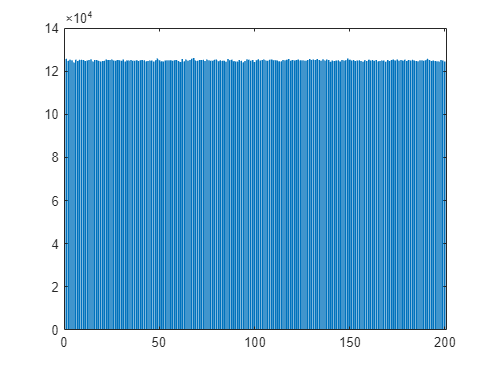

n_runs = 5000000;
n_toChoose = 5;
n_options = 200;
l_numbers = 1:n_options;
results = zeros(n_runs,n_toChoose);
counts = zeros(1,n_options);

parfor i=1:n_runs
    results(i,:) = randMfromN(l_numbers,n_options,n_toChoose);
end

for i=1:n_options
    counts(i) = sum(results(:)==i);
end

bar(counts)

min(counts)

ans = 124063

mean(counts)

ans = 125000

max(counts)

ans = 126058

expected = n_toChoose/n_options*n_runs

expected = 125000


std(counts)

ans = 336.8641